% Оптимизация портфеля по Марковичу (Mean-Variance Optimization)
% Минимизация дисперсии при заданной ожидаемой доходности

clc;
clear;
close all;

%% Входные данные: ожидаемые доходности и ковариационная матрица
% Пример для 3 акций (можно заменить на реальные данные)
mu = [0.10; 0.12; 0.08];  % Ожидаемые доходности (годовые)
Sigma = [0.04  0.002  0.001; ...
        0.002  0.09  -0.003; ...
        0.001 -0.003  0.05];  % Ковариационная матрица

n = length(mu);  % Количество активов

%% Целевая доходность портфеля (варьируемый параметр)
target_return = 0.10;  % 10% годовых

%% Постановка задачи оптимизации
% Целевая функция: минимизация дисперсии = w' * Sigma * w
f = @(w) w' * Sigma * w;

% Линейные ограничения:
Aeq = ones(1, n);  % Сумма весов равна 1
beq = 1;

% Линейное ограничение на доходность: w' * mu = target_return
A = -mu';  % Переносим в левую часть: -mu' * w <= -target_return
b = -target_return;

% Ограничения на неотрицательность весов (длинные позиции)
lb = zeros(n, 1);  % w_i >= 0
ub = ones(n, 1);   % w_i <= 1

%% Решение задачи квадратичной оптимизации
[w_opt, var_opt] = quadprog(Sigma, [], A, b, Aeq, beq, lb, ub);


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



% Применим fmincon (альтернатива для гибкости)
% options = optimoptions('fmincon','Algorithm','sqp');
% [w_opt, var_opt] = fmincon(f, ones(n,1)/n, A, b, Aeq, beq, lb, ub, [], options);

%% Результаты
fprintf('Оптимальные веса портфеля:\n');

Оптимальные веса портфеля:


for i = 1:n
    fprintf('Актив %d: %.4f\n', i, w_opt(i));
end

Актив 1: 0.4539
Актив 2: 0.2730
Актив 3: 0.2730


fprintf('\nМинимальная дисперсия портфеля: %.6f\n', var_opt);


Минимальная дисперсия портфеля: 0.009488


fprintf('Ожидаемая доходность портфеля: %.4f (%.2f%%)\n', w_opt' * mu, 100 * w_opt' * mu);

Ожидаемая доходность портфеля: 0.1000 (10.00%)



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because

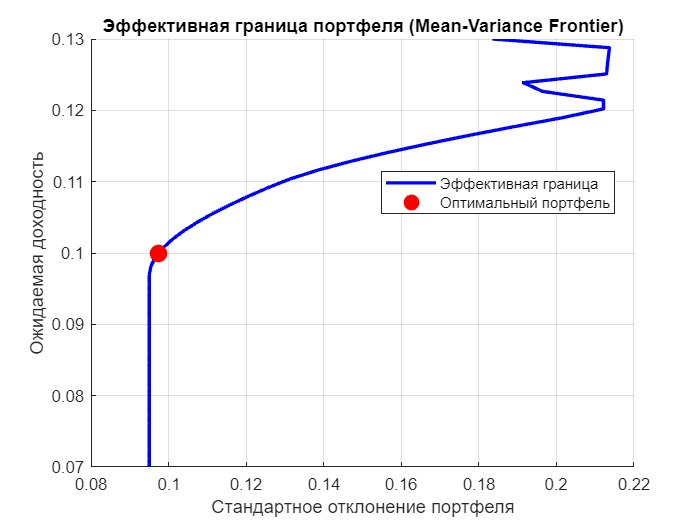


%% Визуализация портфеля (только для 2-3 активов)
if n <= 3
    figure;
    hold on;
    grid on;
    title('Эффективная граница портфеля (Mean-Variance Frontier)');

    % Генерируем несколько целевых доходностей
    target_returns = linspace(min(mu)-0.01, max(mu)+0.01, 50);
    variances = zeros(size(target_returns));
    weights = zeros(n, length(target_returns));

    for i = 1:length(target_returns)
        beq_temp = target_returns(i);
        [w_temp, var_temp] = quadprog(Sigma, [], -mu', -beq_temp, Aeq, 1, lb, ub);
        variances(i) = var_temp;
        weights(:,i) = w_temp;
    end

    plot(sqrt(variances), target_returns, 'b-', 'LineWidth', 2);
    plot(sqrt(var_opt), target_return, 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r');
    xlabel('Стандартное отклонение портфеля');
    ylabel('Ожидаемая доходность');
    legend('Эффективная граница', 'Оптимальный портфель', 'Location', 'best');
else
    warning('Визуализация возможна только для 2-3 активов.');
end